clc
clear all
%% hermite curve

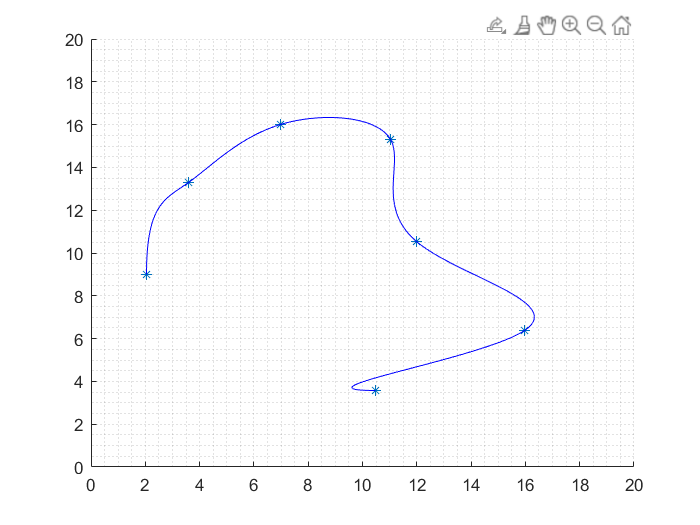

xx = 0


points =

     []



left mouse button picks point


right mouse picks the last point


points =     2.0442    8.9953
    3.5912   13.2944
    6.9797   16.0047
   11.0313   15.3037
   11.9890   10.5374
   15.9669    6.3785
   10.4788    3.5748


B_ =     2.0442    8.9953
    3.5912   13.2944
         0   10.0000
    2.5594    2.3173


B_ =     3.5912   13.2944
    6.9797   16.0047
    2.5594    2.3173
    4.5692    1.7589


B_ =     6.9797   16.0047
   11.0313   15.3037
    4.5692    1.7589
    1.4843   -3.3249


B_ =    11.0313   15.3037
   11.9890   10.5374
    1.4843   -3.3249
    4.5213   -4.8610


B_ =    11.9890   10.5374
   15.9669    6.3785
    4.5213   -4.8610
   -4.7629   -4.0067


B_ =    15.9669    6.3785
   10.4788    3.5748
   -4.7629   -4.0067
   10.0000         0


axis([0 20 0 20])
grid minor
hold on
xx=1;
while xx==1
    xx=xx-1
    points=[]
    n=0;
    disp('left mouse button picks point');
    disp('right mouse picks the last point');
    but=1;
    t=0;
    while but==1
        [x,y,but]=ginput(1);
        plot(x,y,'*');
        n=n+1;
        t=t+1;
        points(:,n)=[x,y];
    end
    
    points=points';
    plu=[0 10];
    pnu=[10 0];
    L=zeros(n,n);
    L(1,1)=1;
    L(1,2)=0;
    L(n,n-1)=0;
    L(n,n)=1;
    for i=1:n-2;
        L(i+1,i)=1;
        L(i+1,i+1)=4;
        L(i+1,i+2)=1;
    end
    R=zeros(n,2);
    R(1,:)=plu;
    R(n,:)=pnu ;
    for i=2:n-1
        R(i,:)=3*(points(i+1,:)-points(i-1,:));
    end
    points
    plot(points(:,1),points(:,2),'*');
    pu=inv(L)*R;
    u=0:0.01:1;
    u=u';
    unit=ones(size(u));
    U=[u.^3 u.^2 u unit];
    M= [ 2 -2 1 1;
        -3 3 -2 -1;
         0 0 1 0;
         1 0 0 0 ];
    for i=1:n-1
        B_=[points(i,:);points(i+1,:);pu(i,:);pu(i+1,:)]
        PP=U*M*B_;
        plot(PP(:,1),PP(:,2),'-',"Color",'b');
    end
end